## Оценка параметров реального китайского привода по данным из csv файла 

### Читаем CSV файл

clear; clc;
%test 1 with delay 9ms dt~12ms, little delay in w in comparision to u
% csv = readmatrix("csv/new_test.csv");
% csv = readmatrix("csv/sin_chi_dt10_floor.csv");
% csv = readmatrix("csv/test_chi.csv");
% csv = readmatrix("csv/sin_chi.csv");
% csv = readmatrix("csv/chi_reverse_sin_dt10.csv");
% csv = readmatrix("csv/chi_sin_stm_kf_test.csv");
% csv = readmatrix("csv/chi_stall_test.csv");
% csv = readmatrix("csv/chi_sin_stall_test.csv");
csv = readmatrix("csv/rchi_step_test.csv");
% csv = readmatrix("csv/rchi_sin1.csv");
% csv = readmatrix("csv/rchi_6v_test.csv");

crop = 10;
data_length = length(csv(:,2))-1 - crop

data_length = 5867

time = csv(2:data_length+1, 2);    % мкс
% q_orig = csv(2:data_length+1, 3) * pi/180;  % рад
% w_orig = csv(2:data_length+1, 4) * pi/180;  % рад/c
% dw_orig = csv(2:data_length+1, 5) * pi/180;  % рад/c^2
input = csv(2:data_length+1, 6) / 100 * 6;    % В
% current = csv(2:data_length+1, 7);  % А
current = csv(2:data_length+1, 7) - 0.048;  % А

% input = -input;

q_orig = csv(2:data_length+1, 3);  % рад
w_orig = csv(2:data_length+1, 4);  % рад/c
dw_orig = csv(2:data_length+1, 5);  % рад/c^2

t_start = time(1);
time = (time - t_start)/1000000;    % с
tf = time(data_length);

dt_sum = 0;
for k = 2:data_length
    dt = time(k) - time(k-1);
    dt_sum = dt_sum + dt;
end

dt = dt_sum/(data_length-1)

dt = 0.0095


% w_orig = smooth(w_orig, 5);
% dw_orig = smooth(dw_orig, 10);
% current = smooth(current, 2);

Km = 0.2923;
Lam = 0.0019; 
J = 0.0011;
M_ext_orig = J*dw_orig + Lam*w_orig - Km*current;
M_ext_orig = smooth(M_ext_orig, 10);

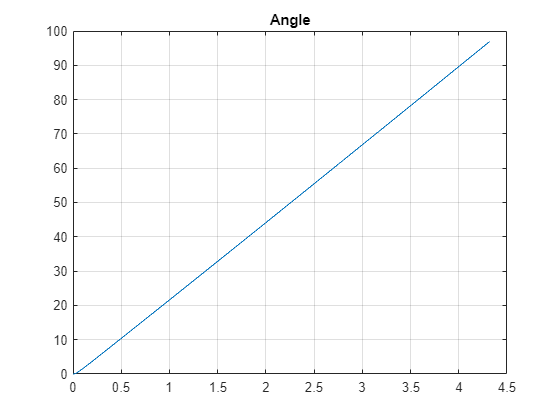

figure;
plot(time, q_orig)
title("Angle")
xlim("auto")
ylim("auto")
grid on

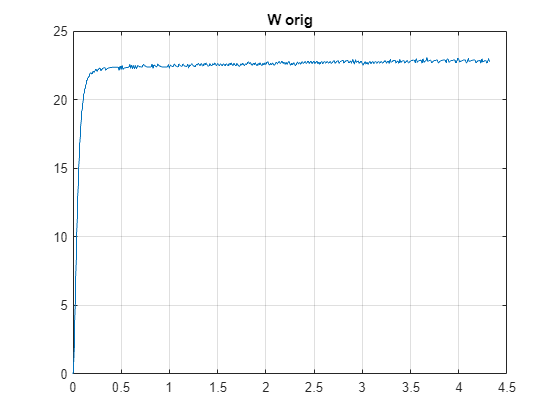


figure;
plot(time, w_orig)
title("W orig")
xlim("auto")
ylim("auto")
grid on

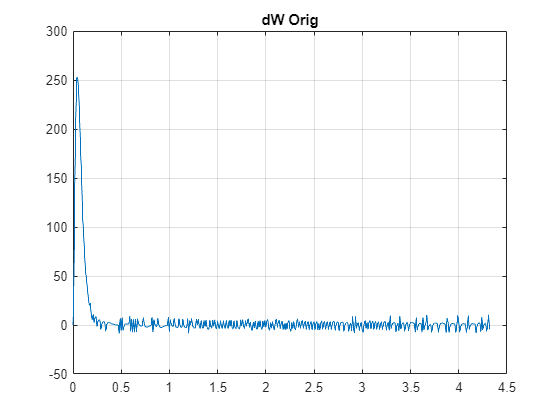


figure;
plot(time, dw_orig)
title("dW Orig")
xlim("auto")
ylim("auto")
grid on

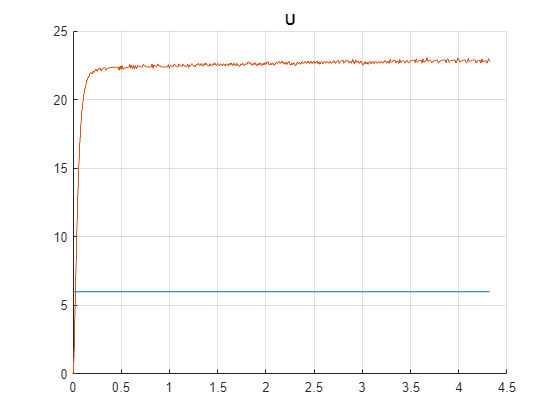


figure;
hold on
plot(time, input)
plot(time, w_orig)
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

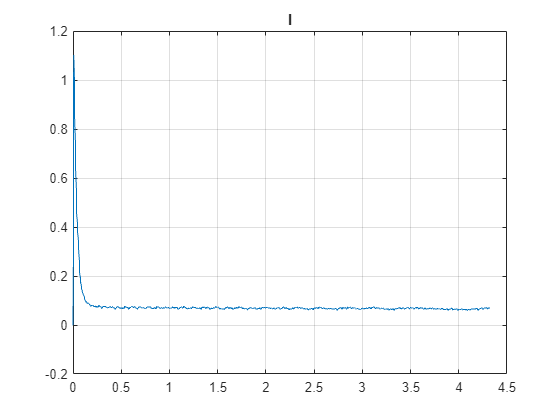


figure;
plot(time, current)
title("I")
xlim("auto")
ylim("auto")
grid on

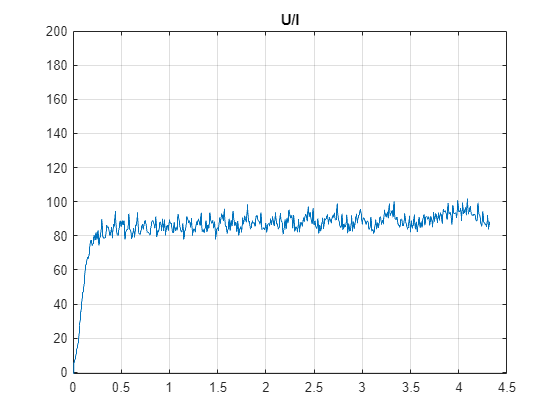


figure;
plot(time, input./current)
title("U/I")
xlim("auto")
% ylim("auto")
ylim([-1 200])
grid on

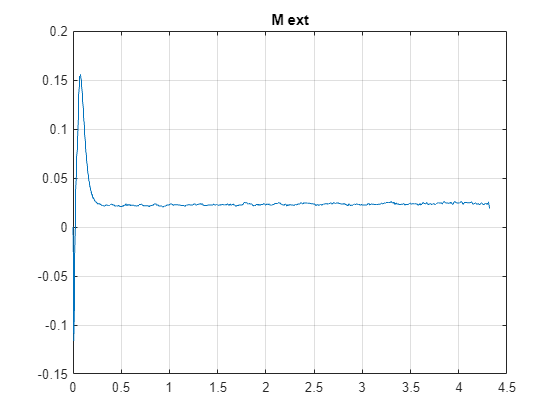


figure;
plot(time, M_ext_orig)
title("M ext")
xlim("auto")
ylim("auto")
grid on

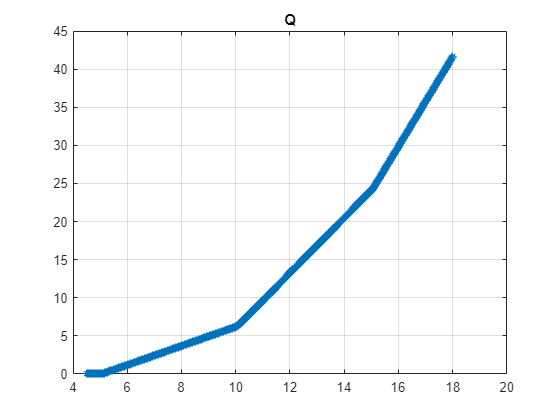

% start = 3500;
% finish = 3550;

start = 500;
finish = 2000;

figure;
plot(time(start:finish), q_orig(start:finish), '*-')
% plot(time(start:finish), ticks(start:finish))
title("Q")
xlim("auto")
ylim("auto")
grid on

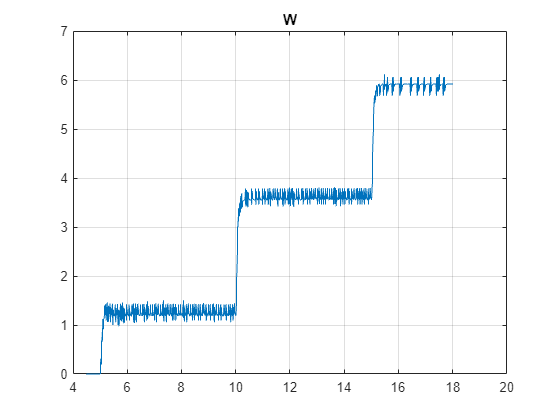


figure;
% plot(time(start:finish), w_orig(start:finish), '*-')
plot(time(start:finish), w_orig(start:finish))
title("W")
xlim("auto")
ylim("auto")
grid on

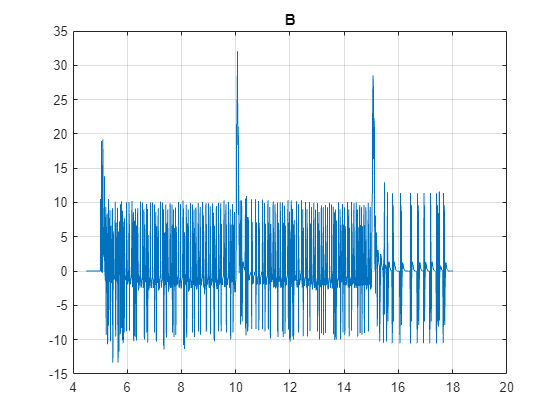


figure;
% plot(time(start:finish), dw_orig(start:finish), '*-')
plot(time(start:finish), dw_orig(start:finish))
title("B")
xlim("auto")
ylim("auto")
grid on

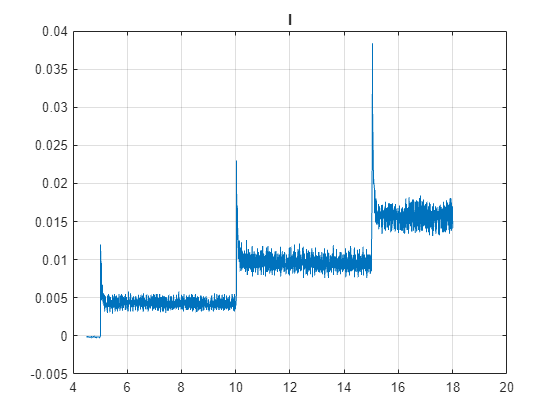


figure;
% plot(time(start:finish), current(start:finish), '*-')
plot(time(start:finish), current(start:finish))
title("I")
xlim("auto")
ylim("auto")
grid on

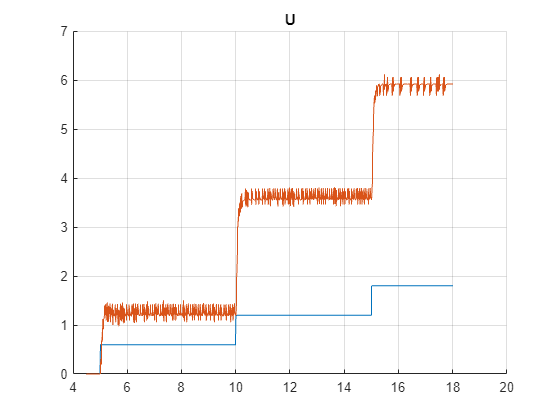


figure;
hold on
% plot(time(start:finish), input(start:finish), '*-')
plot(time(start:finish), input(start:finish))
plot(time(start:finish), w_orig(start:finish))
hold off
title("U")
xlim("auto")
ylim("auto")
grid on

### Parameters identification with kalman filter model with load

% from offline parameter identification CHI + KF (better)
L = 0.0241;
R = 19.7430;
Kw = 0.2203;
Km = 0.2203;
J = 0.0005;
Lam = 0.0019; 

% offline step test + estimation for rest of params with KF
L = 0.0314;
J = 0.0011;
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 

%some v1
L = 1.8317;
R = 11.8417;
Kw = 0.2365;
Km = 6.5429e-05;
J = 5.9580e-08;
Lam = 2.0960e-07;

% some v2
% L = 1.8317;
% R = 11.8419;
% Kw = 0.2365;
% Km = 0.1839;
% J = 1.6703e-04;
% Lam = 5.8939e-04;

%from calculator
Lam = 0.0013;
R = 4.8387;
Kw = 0.2696;
L = 3.3525;
J = 9.4270e-05;
Km = 0.4032;

L = eL;
R = eR;
Kw = eKw;
Km = eKm;
J = eJ;
Lam = eLam;


% L = 0.0191;
% m wheel= 0.024 1/2*m*r^2
% J = 0.5*0.024*(0.068/2)^2
    
% random
% L = rand();
% R = rand();
% Kw = rand();
% Km = rand();
% J = rand();
% Lam = rand();

% V3 + load
% x = [w dw I]'
% u = [Mext u]'
A = [-Lam/J      0      Km/J;
     -Km*Kw/(J*L) -Lam/J -Km*R/(J*L);
     -Kw/L       0      -R/L];
B = [1/J 0;
     0   Km/(J*L);
     0   1/L];
C = eye(3);
% D = [0 0 0]';
D = [0 0 0;
     0 0 0]';

C_lqe = [1 0 0;
         0 1 0;
         0 0 0];
[Te, De] = eig(A);
% Cc = ctrb(A,B)
% Cob = obsv(A, C_lqe)
% rank(Cc)
% rank(Cob)

% best for now
% Vd_w = 1e2;
% Vd_dw = 1e3;
% Vd_I = 1;
% Vd = [Vd_w   0    0;
%        0   Vd_dw  0;
%        0     0    Vd_I];
% 
% Vn = [1e1 0 0;
%       0 1e7 0;
%       0 0 1];

Vd_w = 1e2;
Vd_dw = 1e3;
Vd_I = 1;
Vd = [Vd_w   0    0;
       0   Vd_dw  0;
       0     0    Vd_I];

Vn = [1e1 0 0;
      0 1e7 0;
      0 0 1];

dt = 0.01

dt = 0.0100

dt

dt = 0.0100

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     0.9057   -0.0000         0
   -1.8017    0.0320         0
    0.0003   -0.0000         0


"<< " + Kf(1,1) + ", " + Kf(1,2) + ", " + Kf(1,3) + ", " ...
      + Kf(2,1) + ", " + Kf(2,2) + ", " + Kf(2,3) + ", " ...
      + Kf(3,1) + ", " + Kf(3,2) + ", " + Kf(3,3)

ans = "<< 0.90575, -1.8017e-06, 0, -1.8017, 0.031967, 0, 0.0003048, -3.0667e-08, 0"


x = [0 0 0]';
u = [0 0]';
x_arr = zeros(3, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext_arr = zeros(1, data_length);
Mext_est_arr = zeros(1, data_length);

At = expm(A*dt)

At =     0.8556   -0.0000   39.4323
   -2.9563    0.8712 -123.5214
   -0.0007    0.0000    0.9694


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(3))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe)

A_hat =    -0.0501    0.0000   39.4323
   -1.1546    0.8392 -123.5214
   -0.0010    0.0000    0.9694


B_hat = [Bt Kf]

B_hat =    98.5242    0.0605    0.9057   -0.0000         0
 -165.1993   11.7621   -1.8017    0.0320         0
   -0.0404    0.0029    0.0003   -0.0000         0


"<< " + At(1,1) + ", " + At(1,2) + ", " + At(1,3) + ", " ...
      + At(2,1) + ", " + At(2,2) + ", " + At(2,3) + ", " ...
      + At(3,1) + ", " + At(3,2) + ", " + At(3,3)

ans = "<< 0.85561, -2.833e-18, 39.4323, -2.9563, 0.87118, -123.5214, -0.00074141, 3.7163e-21, 0.96944"

"<< " + Bt(1,1) + ", " + Bt(1,2) + ", " ...
      + Bt(2,1) + ", " + Bt(2,2) + ", " ...
      + Bt(3,1) + ", " + Bt(3,2)

ans = "<< 98.5242, 0.060488, -165.1993, 11.7621, -0.040445, 0.002945"

% k_m = 0.004;
k_m = 0.1;
Mext_sum = 0;
Mext = -12.3e-3;
Mext_base = Mext;
w_est_arr = zeros(1, data_length);

% for k = 2:20
for k = 2:data_length
    dt = time(k) - time(k-1);
    u_act = input(k-1);

%     Mext_est_arr(k-1) = -J*dw_orig(k-1) - Lam*w_orig(k-1) + Th_hat(3)*current(k-1);
%     Mext = Mext_est_arr(k-1);

%     Mext = -M_ext_orig(k);

%     u = [Mext input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    u = [0 input(k-1) (C_lqe*[w_orig(k-1) dw_orig(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    
    w_act = x_arr(1, k-1);
    dw_act = x_arr(2, k-1);
    I_act = x_arr(3, k-1);
    dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

%     w_act = x_arr(1, k);
%     dw_act = x_arr(2, k);
%     I_act = x_arr(3, k);
%     dI_act = (x_arr(3, k)-x_arr(3, k-1))/dt;

%     w_act = w_orig(k-1);
%     dw_act = dw_orig(k-1);
%     I_act = current(k-1);
%     dI_act = (current(k)-current(k-1))/dt;

    q_arr(k) = q_arr(k-1) + w_act*dt;

    Mext = J*x_arr(2, k) + Lam*x_arr(1,k) - Km*x_arr(3,k);
%     Mext = J*x_arr(2, k) + Lam*x_arr(1,k) - Km*current(k);
%     Mext = (Mext_base + Mext)/2;
    Mext = Mext_arr(k-1) * (1 - k_m) + k_m * Mext;
%     Mext = -abs(Mext);
%     Mext = -J*x_arr(2, k) - Lam*x_arr(1,k) + Th_hat(3)*x_arr(3,k);
    Mext_arr(k) = real(Mext);
    Mext_sum = Mext_sum + Mext;
    w_est_arr(k) = (u_act-R*1.05*current(k))/(Km*2);
end

Mext_avr = Mext_sum/data_length

Mext_avr = 0.0011

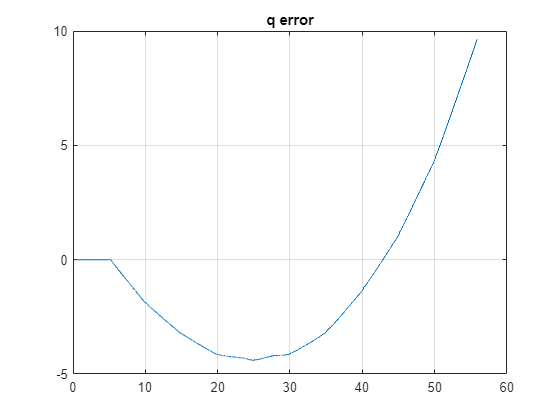

% start = 1;
start = 10;
% finish = 50;
finish = data_length;

figure;
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

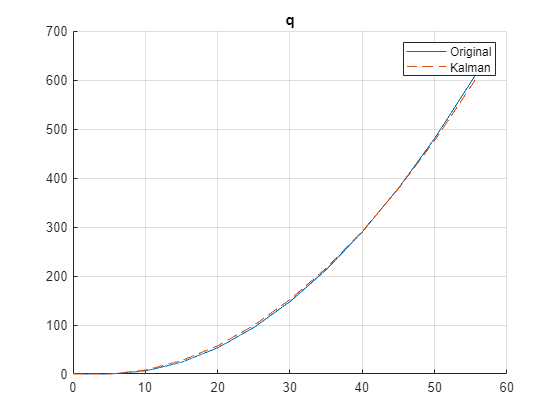


figure;
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Kalman")

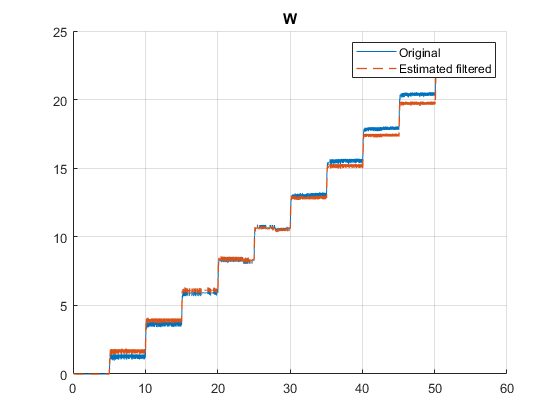


figure;
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

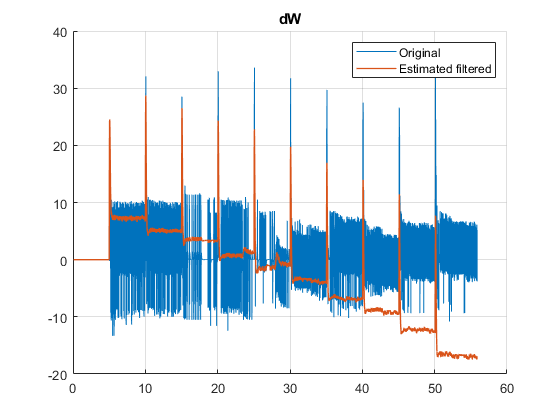


figure;
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)), "LineWidth", 1)
hold off
grid on
title("dW")
xlim("auto")
ylim("auto")
% ylim([-60 60])
legend("Original", "Estimated filtered")

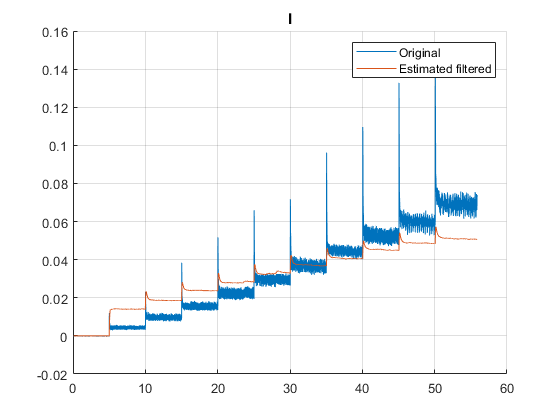


figure;
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(3, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

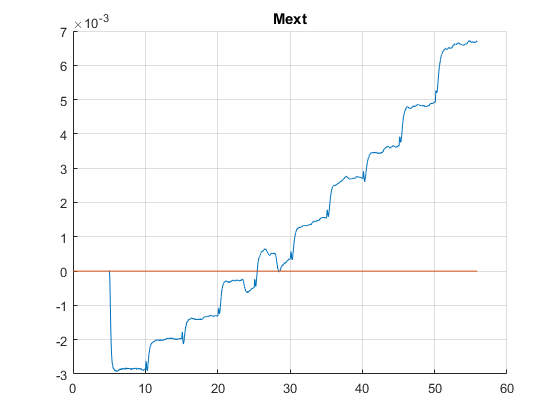


% figure;
% hold on
% plot(time(start:finish), dI_arr(start:finish))
% hold off
% grid on
% title("dI")
% xlim("auto")
% ylim("auto")
% legend("Original", "Estimated filtered")

Mext_est_arr = smooth(Mext_est_arr, 120);
figure;
hold on
plot(time, Mext_arr)
plot(time, Mext_est_arr)
hold off
grid on
title("Mext")
xlim("auto")
ylim("auto")

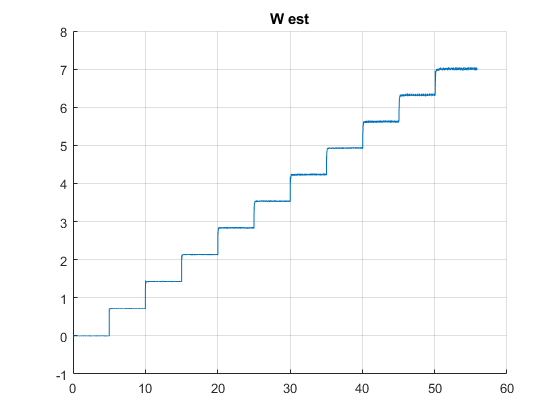


figure;
hold on
plot(time, w_est_arr)
hold off
grid on
title("W est")
xlim("auto")
ylim("auto")

### Parameters identification with kalman filter model with load

% from offline parameter identification CHI + KF (better)
L = 0.0241;
R = 19.7430;
Kw = 0.2203;
Km = 0.2203;
J = 0.0005;
Lam = 0.0019; 

% offline step test + estimation for rest of params with KF
L = 0.0314;
J = 0.0011;
R = 11.8227;
Kw = 0.2923;
Km = Kw;
Lam = 0.0019; 

% L = 0.0191;
    
% random
% L = rand();
% R = rand();
% Kw = rand();
% Km = rand();
% J = rand();
% Lam = rand();

% V4 with load
% x = [w I]'
% u = [Mext u]'
A = [-Lam/J Km/J;
     -Kw/L -R/L];
B = [1/J 0;
     0  1/L];
C = eye(2);
D = [0 0;
    0 0]';

% A = [-Lam/J Km/J; -Kw/L -R/L]
% B = [-1/J 0; 0 1/L]
% C = [1 0; 0 1]
% D = [0 0; 0 0]

C_lqe = [1 0;
         0 0];
[Te, De] = eig(A);
Cc = ctrb(A,B)

Cc = 1.0e+04 *

    0.0909         0   -0.1570    0.8463
         0    0.0032   -0.8463   -1.1991


Cob = obsv(A, C_lqe)

Cob =     1.0000         0
         0         0
   -1.7273  265.7273
         0         0


rank(Cc)

ans = 2

rank(Cob)

ans = 2


% best for now
Vd_w = 1e5;
Vd_I = 1;
Vd = [Vd_w   0;
       0   Vd_I];

Vn = [1e2 0;
      0 1];

dt = 0.01

dt = 0.0100

dt

dt = 0.0100

[Kf, Pf, Ef] = lqed(A, Vd, C_lqe, Vd, Vn, dt);
Kf

Kf =     1.0000         0
   -0.0183         0


% "<< " + Kf(1,1) + ", " + Kf(1,2) + ", " + Kf(1,3) + ", " ...
%       + Kf(2,1) + ", " + Kf(2,2) + ", " + Kf(2,3) + ", " ...
%       + Kf(3,1) + ", " + Kf(3,2) + ", " + Kf(3,3)

x = [0 0]';
u = [0 0]';
x_arr = zeros(2, data_length);
q_arr = zeros(1, data_length);
dI_arr = zeros(1, data_length);
Mext_arr = zeros(1, data_length);
Mext_est_arr = zeros(1, data_length);

At = expm(A*dt)

At =     0.9356    0.6576
   -0.0230    0.0081


Bt = Te*inv(De)*inv(Te)*(Te*expm(De*dt)*inv(Te)-eye(2))*B;
Bt = real(Bt);
A_hat = (At-Kf*C_lqe)

A_hat =    -0.0644    0.6576
   -0.0047    0.0081


B_hat = [Bt Kf]

B_hat =     8.8350    0.1628    1.0000         0
   -0.1628    0.0799   -0.0183         0


% "<< " + At(1,1) + ", " + At(1,2) + ", " + At(1,3) + ", " ...
%       + At(2,1) + ", " + At(2,2) + ", " + At(2,3) + ", " ...
%       + At(3,1) + ", " + At(3,2) + ", " + At(3,3)
% "<< " + Bt(1,1) + ", " + Bt(1,2) + ", " ...
%       + Bt(2,1) + ", " + Bt(2,2) + ", " ...
%       + Bt(3,1) + ", " + Bt(3,2)

% k_m = 0.004;
k_m = 0.1;
Mext_sum = 0;
Mext = -12.3e-3;
% Mext = 0;
w_est_arr = zeros(1, data_length);
dw_arr = zeros(1, data_length);

% for k = 2:10
for k = 2:data_length
    dt = time(k) - time(k-1);
    u_act = input(k-1);

    u = [Mext input(k-1) (C_lqe*[w_orig(k-1) current(k-1)]')']';
    x_arr(:, k) = A_hat*x_arr(:, k-1)+B_hat*u;
    x_arr(:, k) = real(x_arr(:, k));
    
    w_act = x_arr(1, k-1);
%     dw_act = x_arr(2, k-1);
    dw_act = (x_arr(1, k)-x_arr(1, k-1))/dt;
    dw_act = dw_arr(k-1) * (1-0.1) + 0.1*dw_act;
    I_act = x_arr(2, k-1);
    dI_act = (x_arr(2, k)-x_arr(2, k-1))/dt;

%     w_act = w_orig(k-1);
%     dw_act = dw_orig(k-1);
%     I_act = current(k-1);
%     dI_act = (current(k)-current(k-1))/dt;

    q_arr(k) = q_arr(k-1) + w_act*dt;

    Mext = J*dw_act + Lam*x_arr(1,k) - Km*x_arr(2,k);
%     Mext = Lam*x_arr(1,k) - Km*x_arr(2,k); % no dw
    Mext = Mext_arr(k-1) * (1 - k_m) + k_m * Mext;
    Mext = -abs(Mext);
    Mext_arr(k) = real(Mext);
    Mext_sum = Mext_sum + Mext;
    w_est_arr(k) = (u_act-R*1.05*I_act)/(Km*2);
    dw_arr(k) = dw_act;
end

Mext_avr = Mext_sum/data_length

Mext_avr = -0.0015

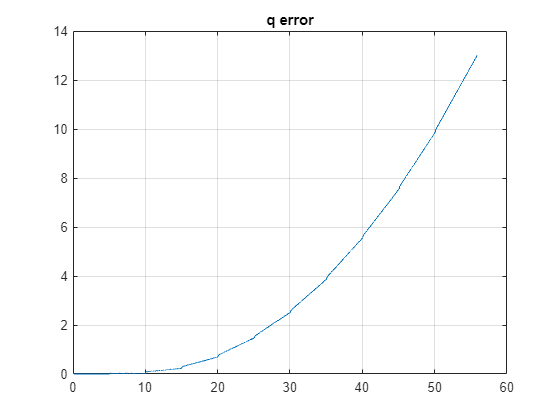

start = 1;
% start = 20;
% finish = 1500;
finish = data_length;

figure;
plot(time(start:finish), (q_orig(start:finish)'-real(q_arr(start:finish))))
% plot(time, q_arr)
grid on
title("q error")
xlim("auto")
ylim("auto")

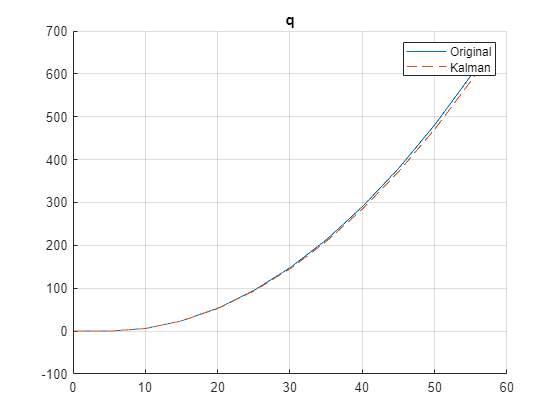


figure;
hold on
plot(time(start:finish), q_orig(start:finish))
plot(time(start:finish), q_arr(start:finish), "--")
hold off
grid on
title("q")
xlim("auto")
ylim("auto")
legend("Original", "Kalman")

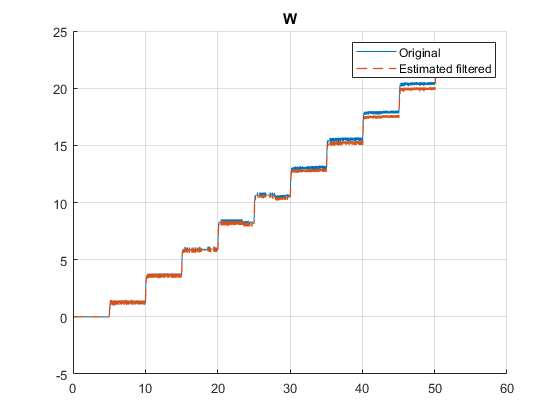


figure;
hold on
plot(time(start:finish), w_orig(start:finish))
plot(time(start:finish), x_arr(1, start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("W")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

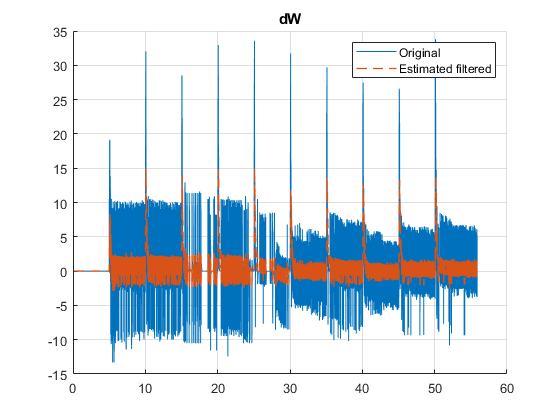


figure;
hold on
plot(time(start:finish), dw_orig(start:finish))
plot(time(start:finish), dw_arr(start:finish), "LineWidth", 1, "LineStyle", "--")
hold off
grid on
title("dW")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

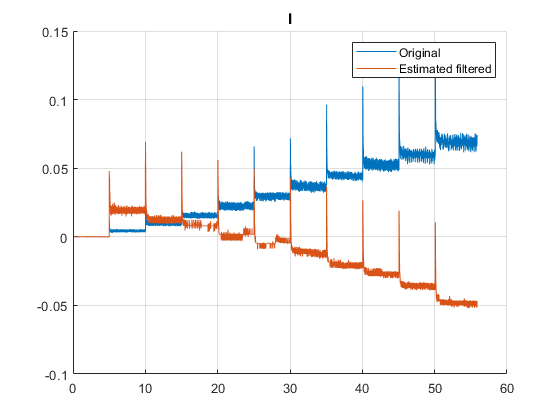


figure;
hold on
plot(time(start:finish), current(start:finish))
plot(time(start:finish), x_arr(2, (start:finish)))
hold off
grid on
title("I")
xlim("auto")
ylim("auto")
legend("Original", "Estimated filtered")

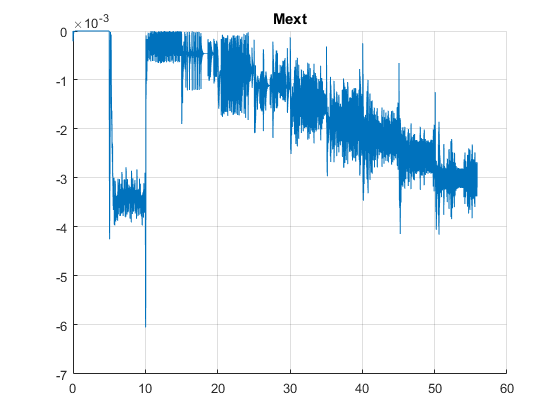


Mext_est_arr = smooth(Mext_est_arr, 120);
figure;
hold on
plot(time, Mext_arr)
% plot(time, Mext_est_arr)
hold off
grid on
title("Mext")
xlim("auto")
ylim("auto")

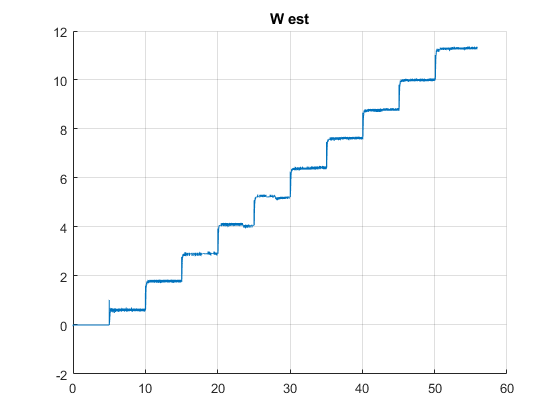


figure;
hold on
plot(time, w_est_arr)
hold off
grid on
title("W est")
xlim("auto")
ylim("auto")

% Ah = [-eLam/eJ eKm/eJ; -eKw/eL -eR/eL];
% Bh = [-1/eJ 0; 0 1/eL];
% C = [1 0; 0 1];
% D = [0 0; 0 0];
% 
% A;
% A = Ah
% B;
% B = Bh

Amp = 3;
Bias = 3;
W = 1;
fi = 3.1415;
Mext = 6e-3;

Const_input = [Amp Bias W fi Mext];

% out1 = sim('motor_model_sim.slx', tf);
% o = out1.simout;

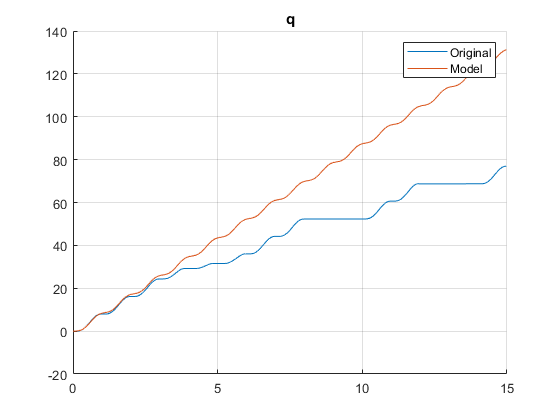

figure
hold on
plot(time, q_orig)
plot(o.q)
hold off
grid on
title("q")
legend("Original", "Model")

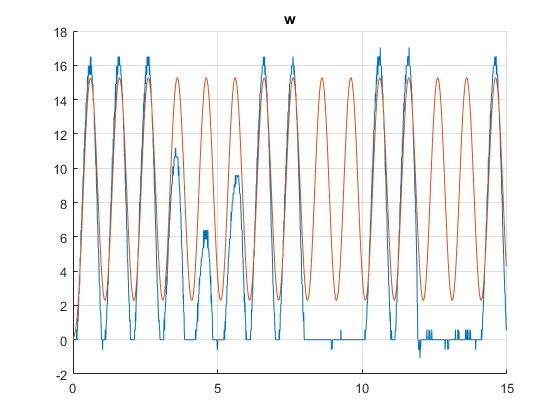


figure
hold on
plot(time, w_orig)
plot(o.w)
hold off
grid on
title("w")

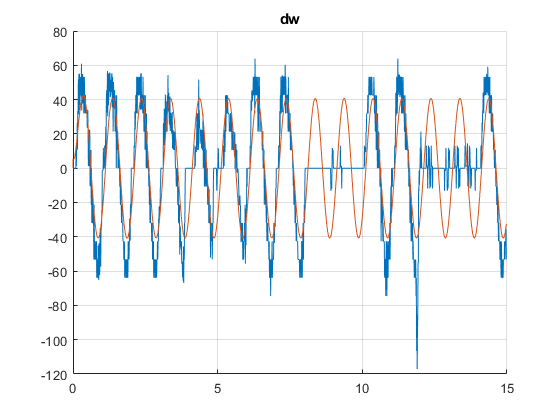


figure
hold on
plot(time, dw_orig)
plot(o.dw)
hold off
grid on
title("dw")

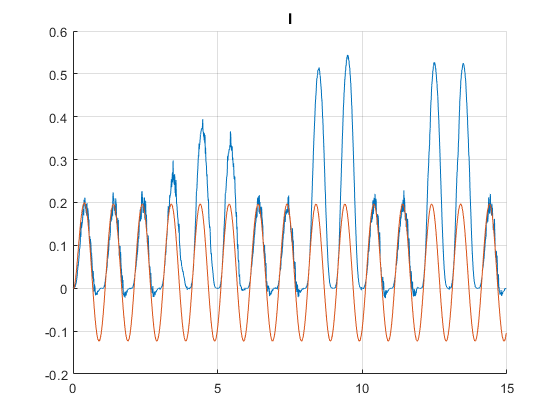


figure
hold on
plot(time, current)
plot(o.I)
hold off
grid on
title("I")

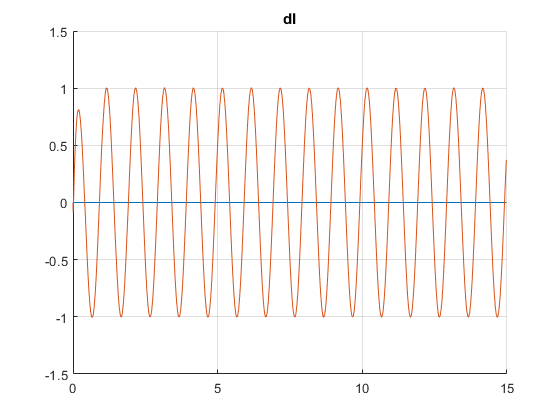


figure
hold on
plot(time, dI_arr)
plot(o.dI)
hold off
grid on
title("dI")